clear 
clc

load permittivityDC
load GP

A = GP;
AA = permittivityDC;

GP = repmat(GP,[1,32]);
GP = reshape(GP,[32,32,1,32,50,10]);

r1 = randperm(50); 
r2 = randperm(10);

for x=1:50
    
for y=1:10
   
    GP(:,:,:,:,x,y)= GP(:,:,:,:,r1(x),r2(y)); 
    
    permittivityDC(:,:,:,:,x,y)= permittivityDC(:,:,:,:,r1(x),r2(y)); 

end

end

GP = reshape(GP,[32,32,1,16000]);
permittivityDC = reshape(permittivityDC,[32,32,1,16000]);



nbertrain = 16000*0.8;  % 提取训练和验证数据 80% 训练，20% 验证

GP_train = (GP(:,:,:,1:nbertrain)); %training的GP
GP_test = (GP(:,:,:,nbertrain+1:16000)); %GP的test的資料

permittivityDC_train = (permittivityDC(:,:,:,1:nbertrain)); %training的permittivityDC
permittivityDC_test = (permittivityDC(:,:,:,nbertrain+1:16000)); %permittivityDC的test的資料


save GP_test GP_test







# Create Deep Learning Network Architecture

Script for creating the layers for a deep learning network with the following properties:

Run the script to create the layers in the workspace variable `lgraph`.

To learn more, see [Generate MATLAB Code From Deep Network Designer](matlab:helpview('deeplearning','generate_matlab_code')).

Auto-generated by MATLAB on 14-Sep-2021 11:07:28

## Create Layer Graph

Create the layer graph variable to contain the network layers.

lgraph = layerGraph();

## Add Layer Branches

Add the branches of the network to the layer graph. Each branch is a linear array of layers.

tempLayers = imageInputLayer([32 32 1],"Name","imageinput");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([3 3],64,"Name","conv_1","Padding","same")
    batchNormalizationLayer("Name","batchnorm_1")
    reluLayer("Name","relu_1")
    convolution2dLayer([3 3],64,"Name","conv_2","Padding","same")
    batchNormalizationLayer("Name","batchnorm_2")
    reluLayer("Name","relu_2")
    convolution2dLayer([3 3],64,"Name","conv_3","Padding","same")
    batchNormalizationLayer("Name","batchnorm_3")
    reluLayer("Name","relu_3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([2 2],"Name","maxpool_1","Padding","same","Stride",[2 2])
    convolution2dLayer([3 3],128,"Name","conv_4","Padding","same")
    batchNormalizationLayer("Name","batchnorm_4")
    reluLayer("Name","relu_4")
    convolution2dLayer([3 3],128,"Name","conv_5","Padding","same")
    batchNormalizationLayer("Name","batchnorm_5")
    reluLayer("Name","relu_5")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([2 2],"Name","maxpool_2","Padding","same","Stride",[2 2])
    convolution2dLayer([3 3],256,"Name","conv_6","Padding","same")
    batchNormalizationLayer("Name","batchnorm_6")
    reluLayer("Name","relu_6")
    convolution2dLayer([3 3],256,"Name","conv_7","Padding","same")
    batchNormalizationLayer("Name","batchnorm_7")
    reluLayer("Name","relu_7")
    transposedConv2dLayer([3 3],256,"Name","transposed-conv_1","Cropping","same","Stride",[2 2])
    batchNormalizationLayer("Name","batchnorm_8")
    reluLayer("Name","relu_8")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    concatenationLayer(3,2,"Name","concat_2")
    convolution2dLayer([3 3],128,"Name","conv_8","Padding","same")
    batchNormalizationLayer("Name","batchnorm_9")
    reluLayer("Name","relu_9")
    convolution2dLayer([3 3],128,"Name","conv_9","Padding","same")
    batchNormalizationLayer("Name","batchnorm_10")
    reluLayer("Name","relu_10")
    transposedConv2dLayer([3 3],128,"Name","transposed-conv_2","Cropping","same","Stride",[2 2])
    batchNormalizationLayer("Name","batchnorm_11")
    reluLayer("Name","relu_11")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    concatenationLayer(3,2,"Name","concat_1")
    convolution2dLayer([3 3],64,"Name","conv_10","Padding","same")
    batchNormalizationLayer("Name","batchnorm_12")
    reluLayer("Name","relu_12")
    convolution2dLayer([3 3],64,"Name","conv_11","Padding","same")
    batchNormalizationLayer("Name","batchnorm_13")
    reluLayer("Name","relu_13")
    convolution2dLayer([1 1],1,"Name","conv_12","Padding","same")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(2,"Name","addition")
    regressionLayer("Name","regressionoutput")];
lgraph = addLayers(lgraph,tempLayers);

% clean up helper variable
clear tempLayers;

## Connect Layer Branches

Connect all the branches of the network to create the network graph.

lgraph = connectLayers(lgraph,"imageinput","conv_1");
lgraph = connectLayers(lgraph,"imageinput","addition/in1");
lgraph = connectLayers(lgraph,"relu_3","maxpool_1");
lgraph = connectLayers(lgraph,"relu_3","concat_1/in1");
lgraph = connectLayers(lgraph,"relu_5","maxpool_2");
lgraph = connectLayers(lgraph,"relu_5","concat_2/in1");
lgraph = connectLayers(lgraph,"relu_8","concat_2/in2");
lgraph = connectLayers(lgraph,"relu_11","concat_1/in2");
lgraph = connectLayers(lgraph,"conv_12","addition/in2");

## Plot Layers

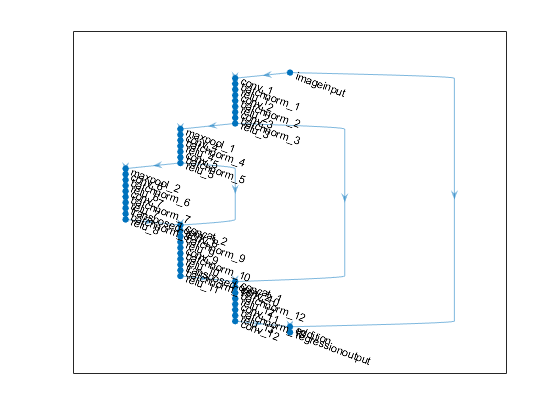

plot(lgraph);


options = trainingOptions('sgdm', ...
    'Momentum', 0.99, ...
    'LearnRateSchedule','piecewise', ...
    "InitialLearnRate",1.0e-6, ...
    'LearnRateDropFactor',0.1, ...
    'L2Regularization',1.0000e-4,...
    'LearnRateDropPeriod',70, ...
    'MaxEpochs',200, ...
    'MiniBatchSize',100, ...
    'Shuffle',"every-epoch",...
    'Plots','training-progress')

options =   TrainingOptionsSGDM with properties:

                        Momentum: 0.9900
                InitialLearnRate: 1.0000e-06
               LearnRateSchedule: 'piecewise'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 70
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                       MaxEpochs: 200
                   MiniBatchSize: 100
                         Verbose: 1
                VerboseFrequency: 50
                  ValidationData: []
             ValidationFrequency: 50
              ValidationPatience: Inf
                         Shuffle: 'every-epoch'
                  CheckpointPath: ''
            ExecutionEnvironment: 'auto'
                      WorkerLoad: []
                       OutputFcn: []
                           Plots: 'training-progress'
              

Training on single GPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:04 |        47.44 |       1125.1 |      1.0000e-06 |
|       1 |          50 |       00:01:03 |        11.66 |         68.0 |      1.0000e-06 |
|       1 |         100 |       00:02:03 |         9.63 |         46.3 |      1.0000e-06 |
|       2 |         150 |       00:03:04 |         6.83 |         23.3 |      1.0000e-06 |
|       2 |         200 |       00:04:05 |         4.07 |          8.3 |      1.0000e-06 |
|       2 |         250 |       00:05:04 |         2.91 |          4.2 |      1.0000e-06 |
|       3 |         300 |  

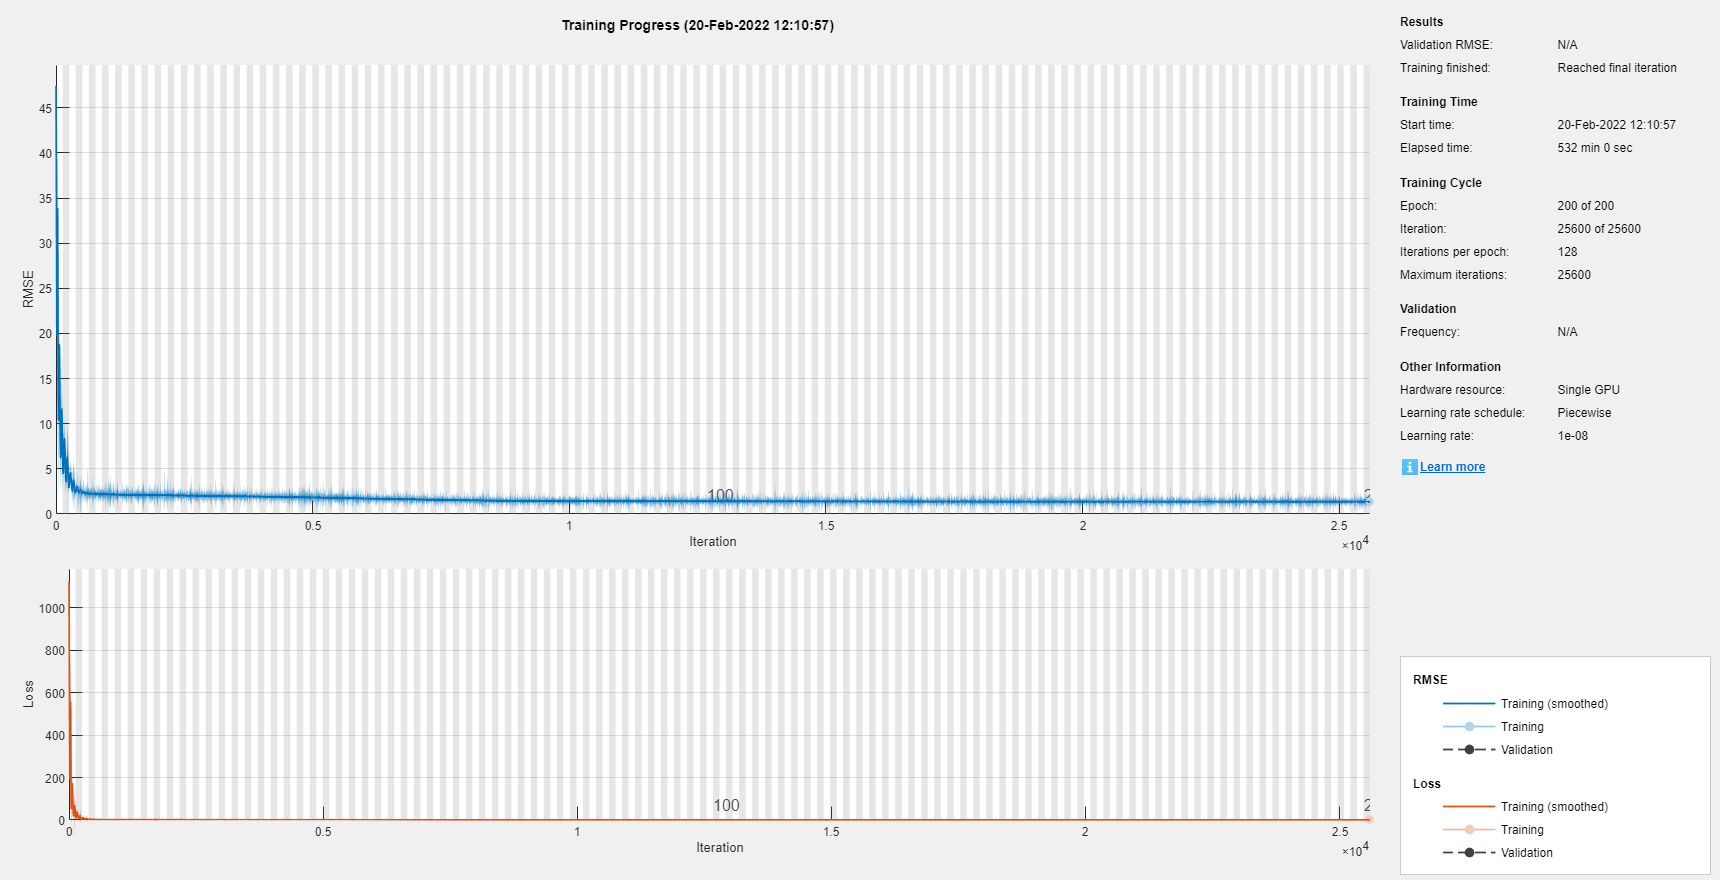


net = trainNetwork(permittivityDC_train,GP_train,lgraph,options);


permittivityDC_test = predict(net,permittivityDC_test);

save permittivityDC_test permittivityDC_test
